# Evidencia 2

## Limpiar el espacio de trabajo

clear; clc; clf; close all;

## Parámetros iniciales

nl = 1; % Número de capas del Imán
ds = 0.1; % Espaciado entre puntos en el espacio
x = (-5:ds:5); y = (-5:ds:5); z = (-3:ds:5); % Vectores de posición en el espacio
Lx = length(x); Ly = length(y); Lz = length(z); % Longitud de los vectores de posición
rw = 0.1; % Radio del alambre del Imán
Icurr = 30; % Corriente eléctrica en Amperios
mo = 4*pi*1e-7; % Permeabilidad magnética del vacío
km = mo*Icurr/(4*pi); % Constante para calcular el campo magnético

## Encontrar índices de corte

cp = find(x<=0); cx = cp(1); % Encontrar índices de valores en x menores o iguales a cero y tomar el primer índice encontrado
cp = find(y<=0); cy = cp(1); % Encontrar índices de valores en y menores o iguales a cero y tomar el primer índice encontrado
cp = find(z<=0); cz = cp(1); % Encontrar índices de valores en z menores o iguales a cero y tomar el primer índice encontrado

## Parámetros del solenoide

N = 12; % Número de vueltas del solenoide
R = 1; % Radio del solenoide
sz = 1; % Espaciado entre vueltas

## Encontrar índice de corte en z e inicializar el contador s

cp = find(z>=-nl*sz*0.5); cz = cp(1);
s = 1;

## Calcular ángulo y longitud de línea

dtheta = 2*pi/N; % Ángulo entre elementos de corriente
dl = R*dtheta; % Longitud de línea entre elementos de corriente
ang = (0:dtheta:2*pi-dtheta); % Vector de ángulos

## Calcular posición y dirección de los elementos de corriente

for I=1:nl

    Px(s:s+N-1) = R*cos(ang); % Posición x de los elementos de corriente
    Py(s:s+N-1) = R*sin(ang); % Posición y de los elementos de corriente
    Pz(s:s+N-1)=-nl/2*sz+(I-1)*sz; % Posición z de los elementos de corriente

    dx(s:s+N-1)=-Py(s:s+N-1)*dtheta; % Componente x del vector dirección de los elementos de corriente
    dy(s:s+N-1)=Px(s:s+N-1)*dtheta; % Componente y del vector dirección de los elementos de corriente

    s=s+N;
end

dz(1:N*nl)=0; % Componente z del vector dirección de los elementos de corriente (cero en este caso)

## Graficar elementos de corriente

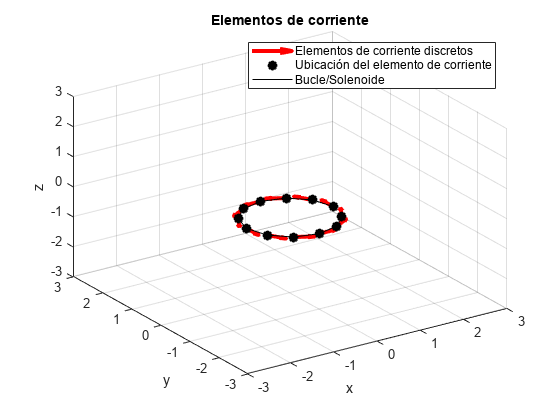

figure(1)
hold on
quiver3(Px,Py,Pz,dx,dy,dz,0.5,'-r','LineWidth',3) % Graficar vectores dirección de los elementos de corriente
plot3(Px,Py,Pz,'*k','LineWidth',5) % Graficar posición de los elementos de corriente
plot3(Px,Py,Pz,'-k','LineWidth',.3) % Graficar línea que une los elementos de corriente

xlabel 'x'
ylabel 'y'
zlabel 'z'
title 'Elementos de corriente'
legend('Elementos de corriente discretos','Ubicación del elemento de corriente','Bucle/Solenoide')
axis([-3 3 -3 3 -3 3])
grid on
view(-34,33)

## Inicializar campo magnético y calcularlo en cada punto del espacio

dBx(1:Lx,1:Ly,1:Lz)=0; dBy=dBx; dBz=dBx;

for I=1:Lx
    for J=1:Ly                  
        for K=1:Lz

            for L=1:nl*N        

                rx=x(I)-Px(L); % Distancia en x entre el punto y el elemento de corriente      
                ry=y(J)-Py(L); % Distancia en y entre el punto y el elemento de corriente      
                rz=z(K)-Pz(L); % Distancia en z entre el punto y el elemento de corriente      

                r=sqrt(rx^2+ry^2+rz^2+rw^2); % Distancia total entre el punto y el elemento de corriente   
                r3=r^3; % Distancia al cubo                     

                dBx(I,J,K)=dBx(I,J,K)+km*dy(L)*rz/r3; % Componente x del campo magnético en el punto
                dBy(I,J,K)=dBy(I,J,K)+km*dx(L)*rz/r3; % Componente y del campo magnético en el punto
                dBz(I,J,K)=dBz(I,J,K)+km*(dx(L)*ry-dy(L)*rx)/r3; % Componente z del campo magnético en el punto

            end

        end
    end
end

## Graficar campo magnético resultante


Bmag=sqrt(dBx.^2+dBy.^2+dBz.^2); % Magnitud del campo magnético    

centery=round(Ly/2); % Índice central en y           
Bx_xz=squeeze(dBx(:,centery,:)); % Campo magnético en el plano xz (componente x)  
Bz_xz=squeeze(dBz(:,centery,:)); % Campo magnético en el plano xz (componente z)   

Bxz=squeeze(Bmag(:,centery,:)); % Magnitud del campo magnético en el plano xz   

figure(3)

hold on

pcolor(x,z,(Bxz').^(1/3)); shading interp; colormap jet; colorbar

h1=streamslice(x,z,Bx_xz',Bz_xz',1);
set(h1,'Color', [0.8 1 0.9]);
xlabel 'x'
ylabel 'z'
title 'Campo magnético de una corriente circular'


## Caída del dipolo

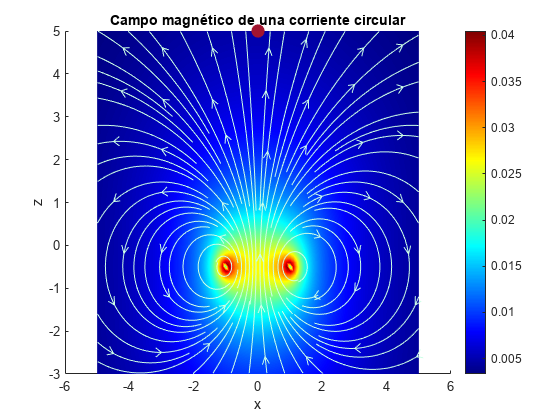

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

ans = 5

mag=10350; % Momento magnético del imán
m=0.004; % Masa del imán en kg

w=m*-9.81; % Peso del imán en N
zo=5; % Posición inicial del imán

dt=0.05; % Paso de tiempo

zm(1)=zo; % posición del imán
zmfree(1)=zo; % posición del imán (caso de caída libre)
tt(1)=0; % inicialización del tiempo
vz(1)=0; % velocidad inicial del imán
vzfree(1)=0; % velocidad inicial del imán (caso de caída libre)
cc=1; % contador de índice

path=animatedline('linewidth', 2, 'linestyle', ':', 'color', 'r');

while zm(cc)>-3

    zm(cc)
    addpoints(path,0,zm(cc)); % agregar puntos al camino, centrado en x=0
    head=scatter(0,zm(cc), 100,'filled'); 
    Fm(cc)=(6*mo*Icurr*R^2*mag*(zm(cc)+0.00001))/(4*((zm(cc)+0.00001)^2+R^2)^(5/2)); % Fuerza magnética
    F(cc)=Fm(cc)+w; 
    a=F(cc)/m; % Fuerza total y aceleración total
    pause(0.01)

    zm(cc+1)=zm(cc)+vz(cc)*dt;
end